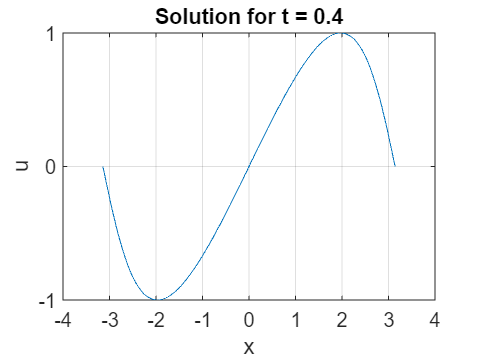

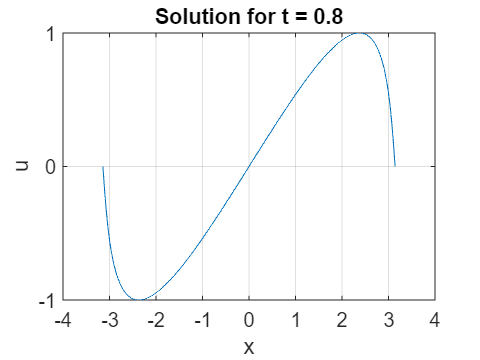

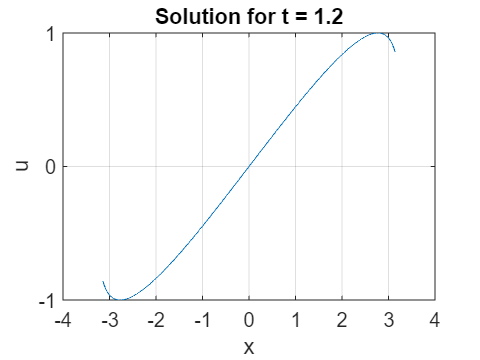

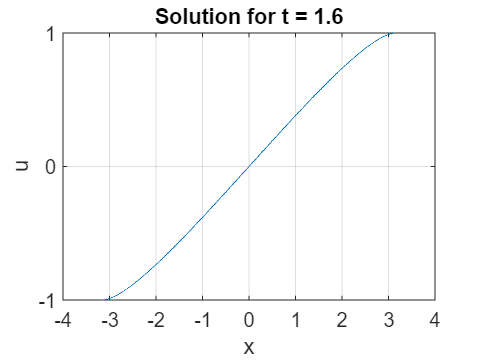

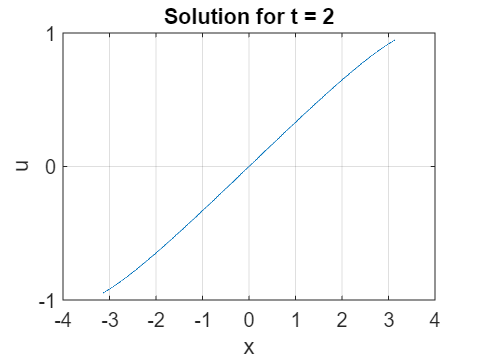

% Sanaz Hami
% Rewriting Problem 2 of Homework 10

% Define the grid
x = linspace(-pi, pi, 1000);
u = zeros(size(x));

% Time steps to evaluate
time_steps = [0.4, 0.8, 1.2, 1.6, 2.0];

% Loop over each time step
for t = time_steps
    % Calculate the solution for each point in x
    for ii = 1:length(x)
        u(ii) = sin(burgers_sine(x(ii), t));
    end

    % Create a new figure for each t
    figure;
    plot(x, u);
    title(['Solution for t = ' num2str(t)]);
    xlabel('x');
    ylabel('u');

    % Set the grid lines at every unit
    xticks(floor(min(x)):ceil(max(x))); % x-axis grid lines
    yticks(floor(min(u)):ceil(max(u))); % y-axis grid lines
    grid on; % Enable the grid
end